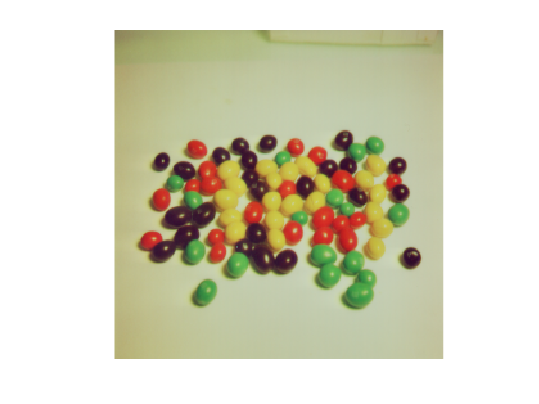

Start=1;
End=8;
decredXor="";
decblueXor="";
decgreenXor="";
for i =1:65536
    decredXor=decredXor+dec2bin(bitxor(bin2dec(extractBetween(redXor,Start,End)),bin2dec(extractBetween(secretkey,Start,End))),8);
    decblueXor=decblueXor+dec2bin(bitxor(bin2dec(extractBetween(blueXor,Start,End)),bin2dec(extractBetween(secretkey,Start,End))),8);
    decgreenXor=decgreenXor+dec2bin(bitxor(bin2dec(extractBetween(greenXor,Start,End)),bin2dec(extractBetween(secretkey,Start,End))),8);
    Start=End+1;
    End=End+8;
end
decredMatrx=zeros(zeros(0,256),zeros(0,256));
decblueMatrx=zeros(zeros(0,256),zeros(0,256));
decgreenMatrx=zeros(zeros(0,256),zeros(0,256));
Start=1;
End=8;
for i=1:256
    for j=1:256
        decredMatrx(i,j)=bin2dec(extractBetween(decredXor,Start,End));
        decblueMatrx(i,j)=bin2dec(extractBetween(decblueXor,Start,End));
        decgreenMatrx(i,j)=bin2dec(extractBetween(decgreenXor,Start,End));
        Start=End+1;
        End=End+8;
    end
end
decrgbImage=cat(3,uint8(decredMatrx),uint8(decgreenMatrx),uint8(decblueMatrx));
imshow(decrgbImage);